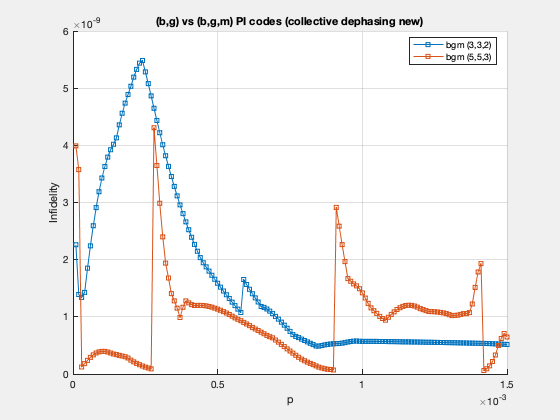

set(0, 'DefaultFigureRenderer', 'painters');  % lightweight renderer
close all;

bg_configs  = []; 
bgm_configs = [3 3 2;
               5 5 3; 
               ];  % (b, g, m)

p_list   = 1e-4:1e-5:1.5e-3;
rho_in   = eye(2)/2;
enc_flag = 1;

fig = figure('Visible','on','Renderer','painters'); hold on;
colors = lines(size(bg_configs,1) + size(bgm_configs,1));
k = 1;

% (b,g) codes
for c = 1:size(bg_configs,1)
    b = bg_configs(c,1); g = bg_configs(c,2);
    [logical0, logical1] = code.bgcode(b, g);
    dim = length(logical0);
    fidelity = zeros(1, numel(p_list));
    for i = 1:numel(p_list)
        model = noisemodel("collectdeph_new", p_list(i), dim);
        [fidelity(i), ~, ~] = optimisation(logical0, logical1, rho_in, model, enc_flag);
    end
    loglog(p_list, abs(1 - fidelity), 'o-', 'Color', colors(k,:), ...
        'DisplayName', sprintf('bg (%d,%d)', b, g), 'LineWidth', 1);
    k = k + 1;
end

% (b,g,m) codes
for c = 1:size(bgm_configs,1)
    b = bgm_configs(c,1); g = bgm_configs(c,2); m = bgm_configs(c,3);
    [logical0, logical1] = code.bgmcode(b, g, m);
    dim = length(logical0);
    fidelity = zeros(1, numel(p_list));
    for i = 1:numel(p_list)
        model = noisemodel("collectdeph_new", p_list(i), dim);
        [fidelity(i), ~, ~] = optimisation(logical0, logical1, rho_in, model, enc_flag);
    end
    loglog(p_list, abs(1 - fidelity), 's-', 'Color', colors(k,:), ...
        'DisplayName', sprintf('bgm (%d,%d,%d)', b, g, m), 'LineWidth', 1);
    k = k + 1;
end

grid on;
xlabel('p');
ylabel('Infidelity');
title('(b,g) vs (b,g,m) PI codes (collective dephasing new)');
legend('Location','best');
hold off;


% Optional save:
% saveas(fig, 'collectdeph_bg_bgm.png');